# Problem 10

For this part of the homework, I referred to my undergrad SVD image compression Matlab code, which explains in detail why we choose the first \nu largest singular values. We see, from the graph of singular values, that the singular values decay to zero significantly after a certain number. (\nu >= 100 is already good enough.)

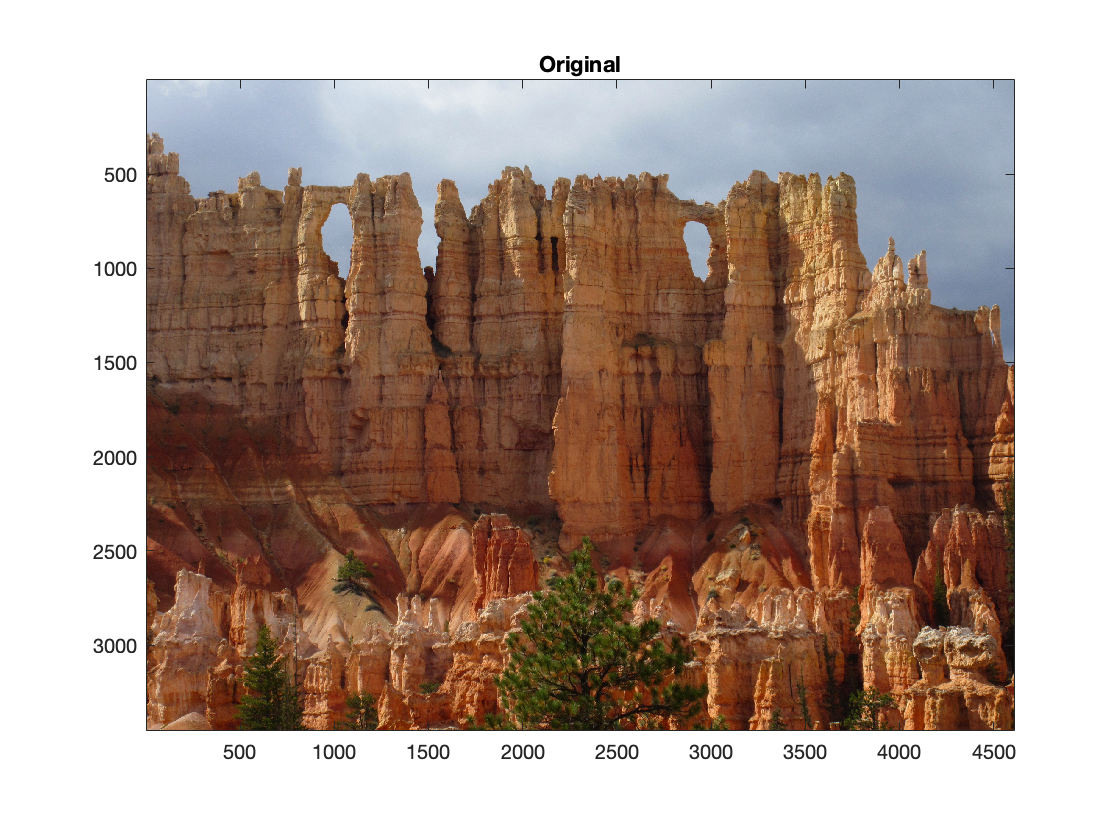

clear; close all; clc;

A = imread('WallOfWindows.jpg','jpg');

% Display Image
image(A)
axis image; title('Original')


A = double(A);

% Spilit each color component
A_red = A(:,:,1);
A_green = A(:,:,2);
A_blue = A(:,:,3);

% SVD on each color component 
% Notice that the singular values are already in decreasing order
[U_r,S_r,V_r]=svd(A_red,0);
[U_g,S_g,V_g]=svd(A_green,0);
[U_b,S_b,V_b]=svd(A_blue,0); 

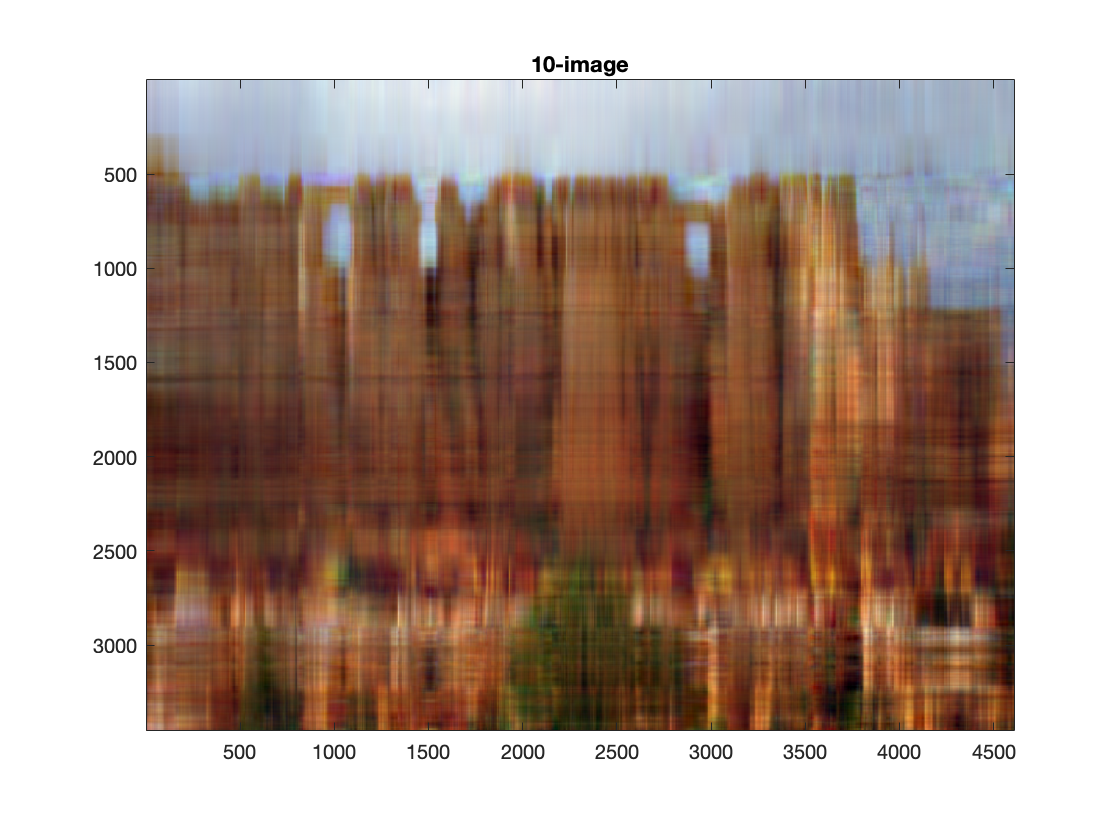

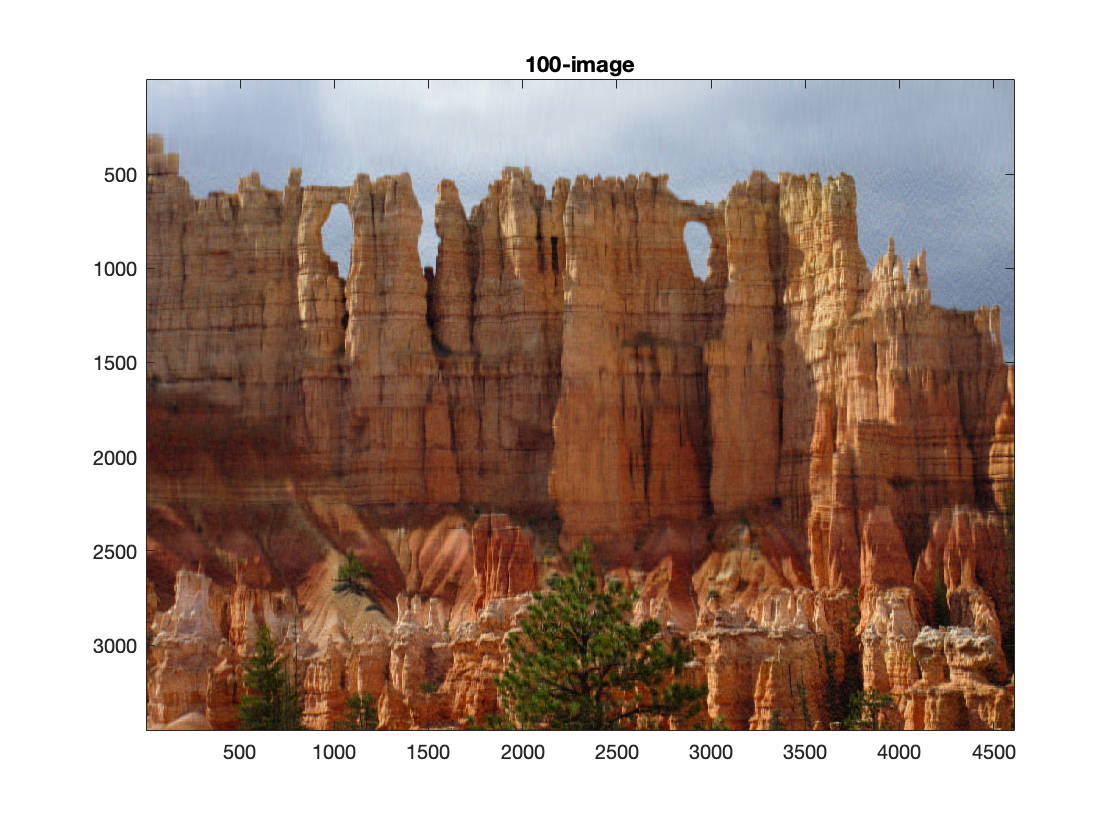

% Set n = 10, 100 and compress image for given n
for n = [10 100]
    A_red_n = U_r(:,1:n) * S_r(1:n,1:n) * V_r(:,1:n)';
    A_green_n = U_g(:,1:n) * S_g(1:n,1:n) * V_g(:,1:n)';
    A_blue_n = U_b(:,1:n) * S_b(1:n,1:n) * V_b(:,1:n)';
    
    % Combine three dimensions
    A_n(:,:,1) = A_red_n;
    A_n(:,:,2) = A_green_n;
    A_n(:,:,3) = A_blue_n;
    
    % Display image
    A_n = uint8(A_n);
    figure,image(A_n); 
    axis image; title([num2str(n),'-image'])
    % saveas(gcf,[num2str(n),'-image'],'pdf')
end

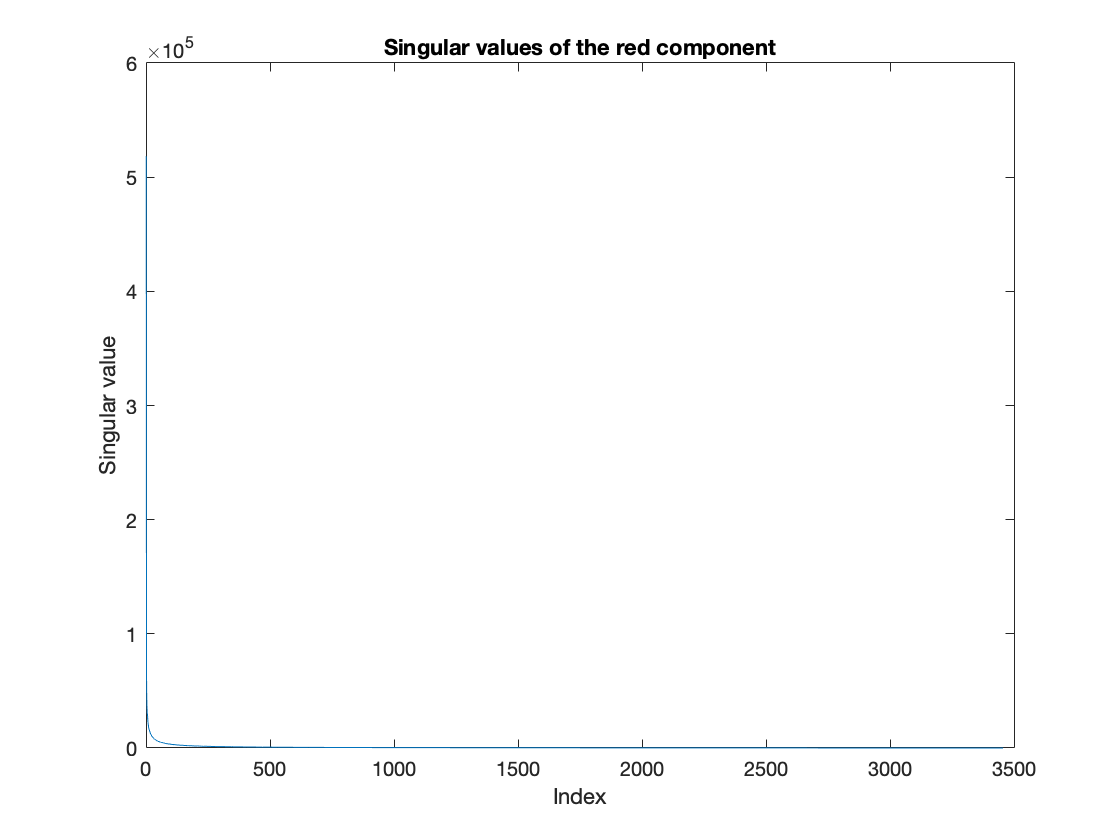

% Graph singular value for each color component
sv_r = ones(3456,1);
sv_g = ones(3456,1);
sv_b = ones(3456,1);
for i = 1:3456
    sv_r(i) = S_r(i,i);
    sv_g(i)= S_g(i,i);
    sv_b(i)= S_b(i,i);
end

index = [1:3456];
plot(index, sv_r)
title('Singular values of the red component')
xlabel('Index')
ylabel('Singular value')

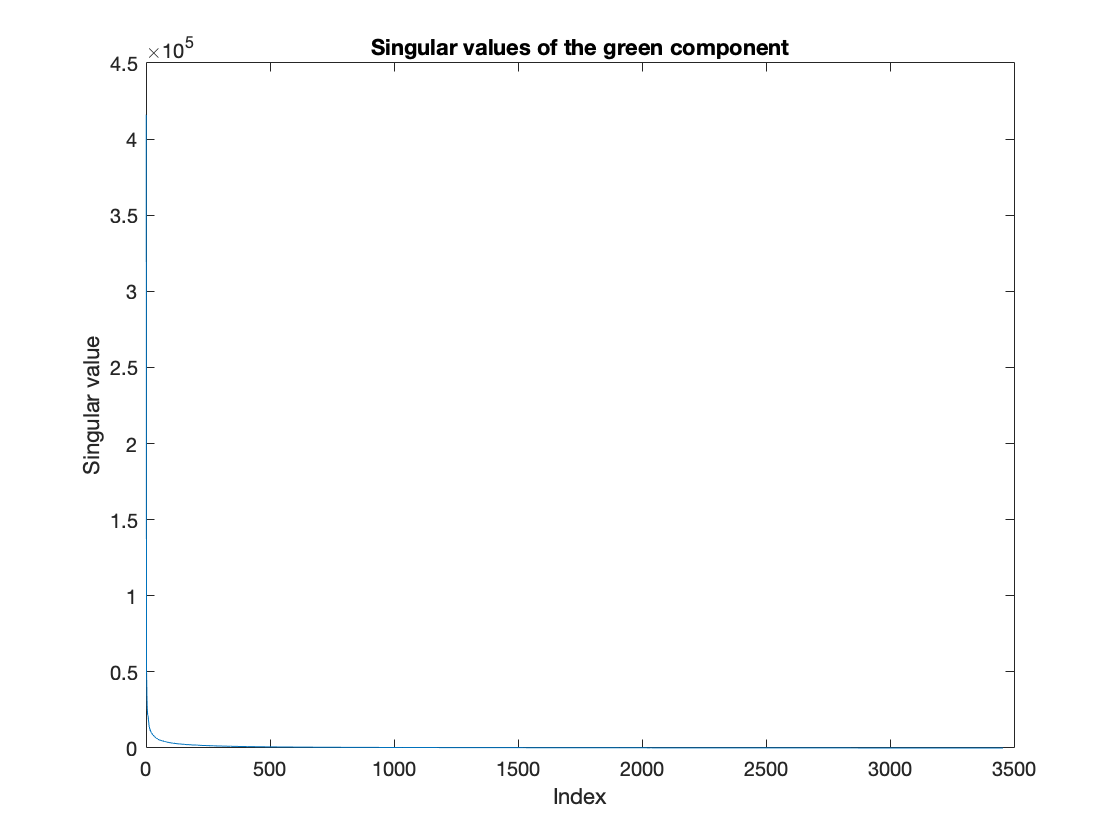


index = [1:3456];
plot(index, sv_g)
title('Singular values of the green component')
xlabel('Index')
ylabel('Singular value')


index = [1:3456];
plot(index, sv_b)
title('Singular values of the blue component')
xlabel('Index')
ylabel('Singular value')